## CST EXAMPLE 

Prof. J. Morlier based on CIVL 7/8117 - Finite Elements in Structural Mechanics

CST solution using 2 element for the lane stress problem given on page 364 of Logan's "First Course in the Finite Element Method" 6th edition.

[http://www.ce.memphis.edu/7117/FEM_codes/Camp's_code/Camp_Matlab_code.html](http://www.ce.memphis.edu/7117/FEM_codes/Camp's_code/Camp_Matlab_code.html)


% Plane stress - plane strain using constant strain triangular elements (CST)
% 
% Input data from Excel spreadsheet "CST_input_data.xlsx"
clear all
clc
format shorteng

filename = 'CST_2_elements.xlsx';

xy = xlsread(filename,'Coordinates','B3:C1000');
C  = xlsread(filename,'Connectivity','B3:D1000');
v  = xlsread(filename,'Poisson','B2:B1000');
t  = xlsread(filename,'Thickness','B2:B1000');
E  = xlsread(filename,'Elasticity','B3:B1000');


TYPE = xlsread(filename,'Plane stress-strain','A2:A2');


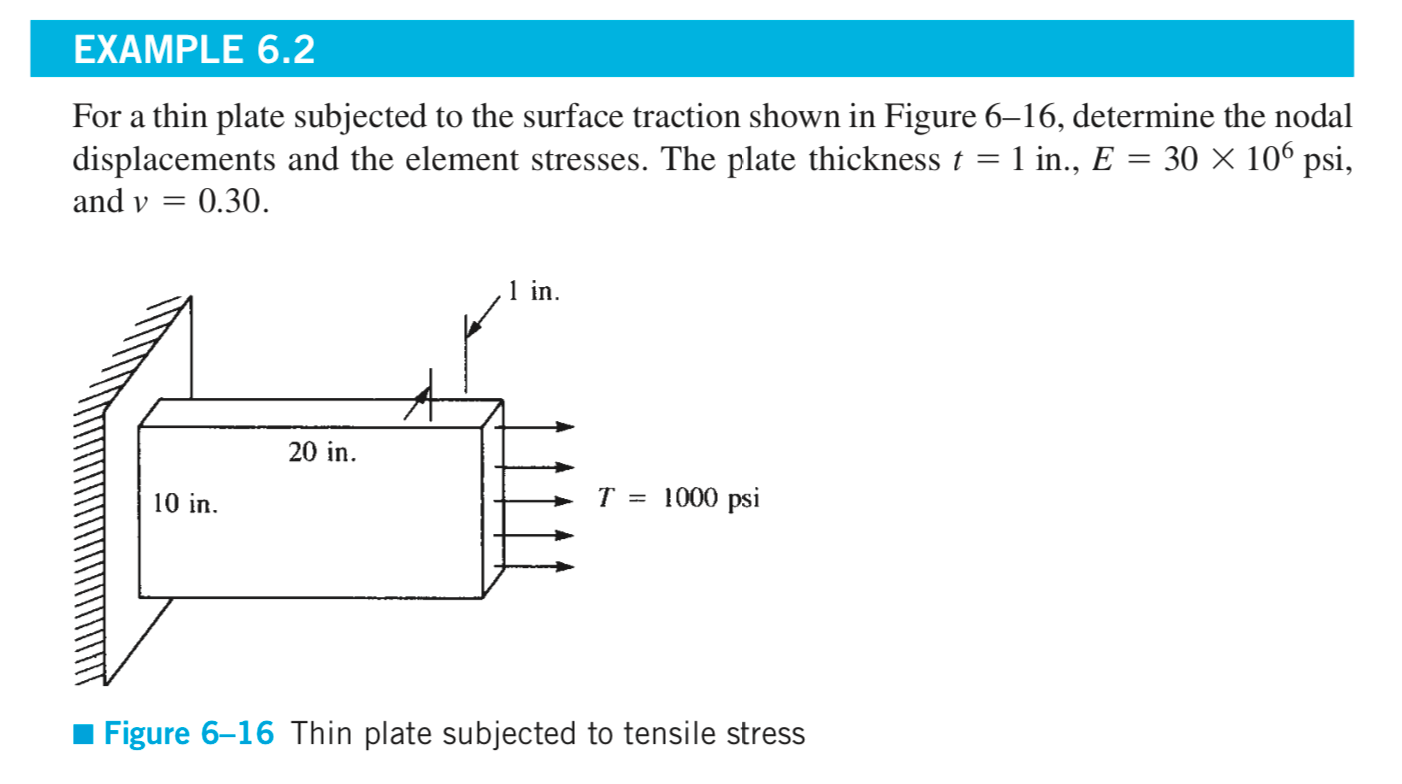

F  = xlsread(filename,'Forces','B2:B1000');
boundary = xlsread(filename,'Boundary','B2:B1000');

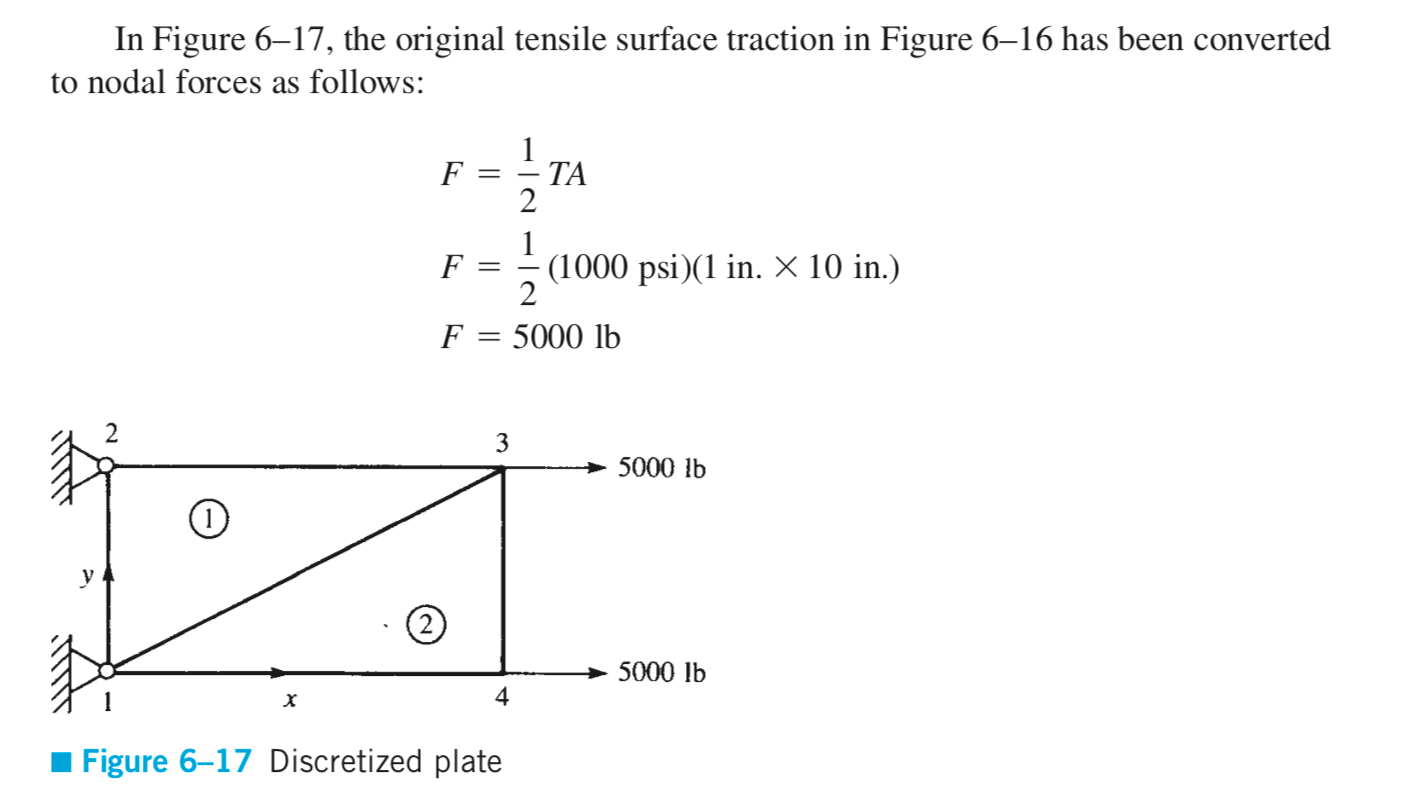

NumEle = size(C,1);
NumNod = max(max(C));
NumDof = 2*NumNod;

K = Stiffness(E,C,xy,t,v,TYPE);

loc     = find(boundary==0);
locFIX  = find(boundary==1);
DofFree = length(loc);

Kelim = zeros(DofFree);
Felim = zeros(DofFree,1);

for i = 1:DofFree
    for j=1:DofFree
        Kelim(i,j) = K(loc(i),loc(j));
    end
end

for i = 1:DofFree
    Felim(i,1) = F(loc(i));
end

d = Kelim\Felim;

displacement = zeros(NumDof,1);
displacement(loc,1) = d

displacement =      0.0000e+000
     0.0000e+000
     0.0000e+000
     0.0000e+000
   609.5810e-006
     4.1633e-006
   663.7043e-006
   104.0833e-006


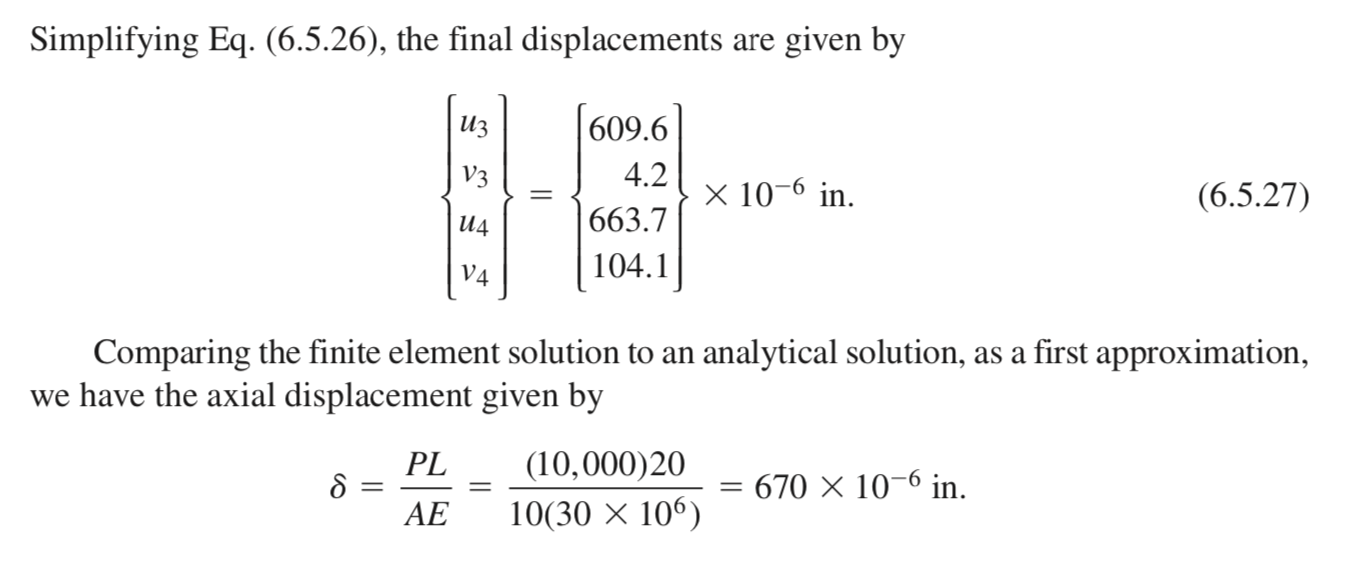


% Element stresses
Se = Stress(E,C,xy,v,TYPE,displacement);

%==============================================================

% Write displacements to Excel file
D = zeros(NumNod,3);
for ip = 1:NumNod
    node = 2*ip;
    D(ip,1) = ip;
    D(ip,2) = displacement(node-1,1);
    D(ip,3) = displacement(node  ,1);
end

header = {'Displacements'};
xlswrite(filename,header,'Displacements','B1')

header1 = {'Node','x','y'};
xlswrite(filename,header1,'Displacements','A2')


s1 = 'A3:C';
s2 = num2str(NumNod+2);
range = strcat(s1,s2);
xlswrite(filename,D,'Displacements',range)


% Write stresses to Excel file
S = zeros(NumEle,4);
for ip = 1:NumEle
    S(ip,1)   = ip;
    S(ip,2:4) = Se(ip,1:3);
end


header = {'Stresses'};
xlswrite(filename,header,'Stresses','B1')

header1 = {'Element','Sx','Sy','Sxy'};
xlswrite(filename,header1,'Stresses','A2')


s1 = 'A3:D';
s2 = num2str(NumEle+2);
range = strcat(s1,s2);
xlswrite(filename,S,'Stresses',range)

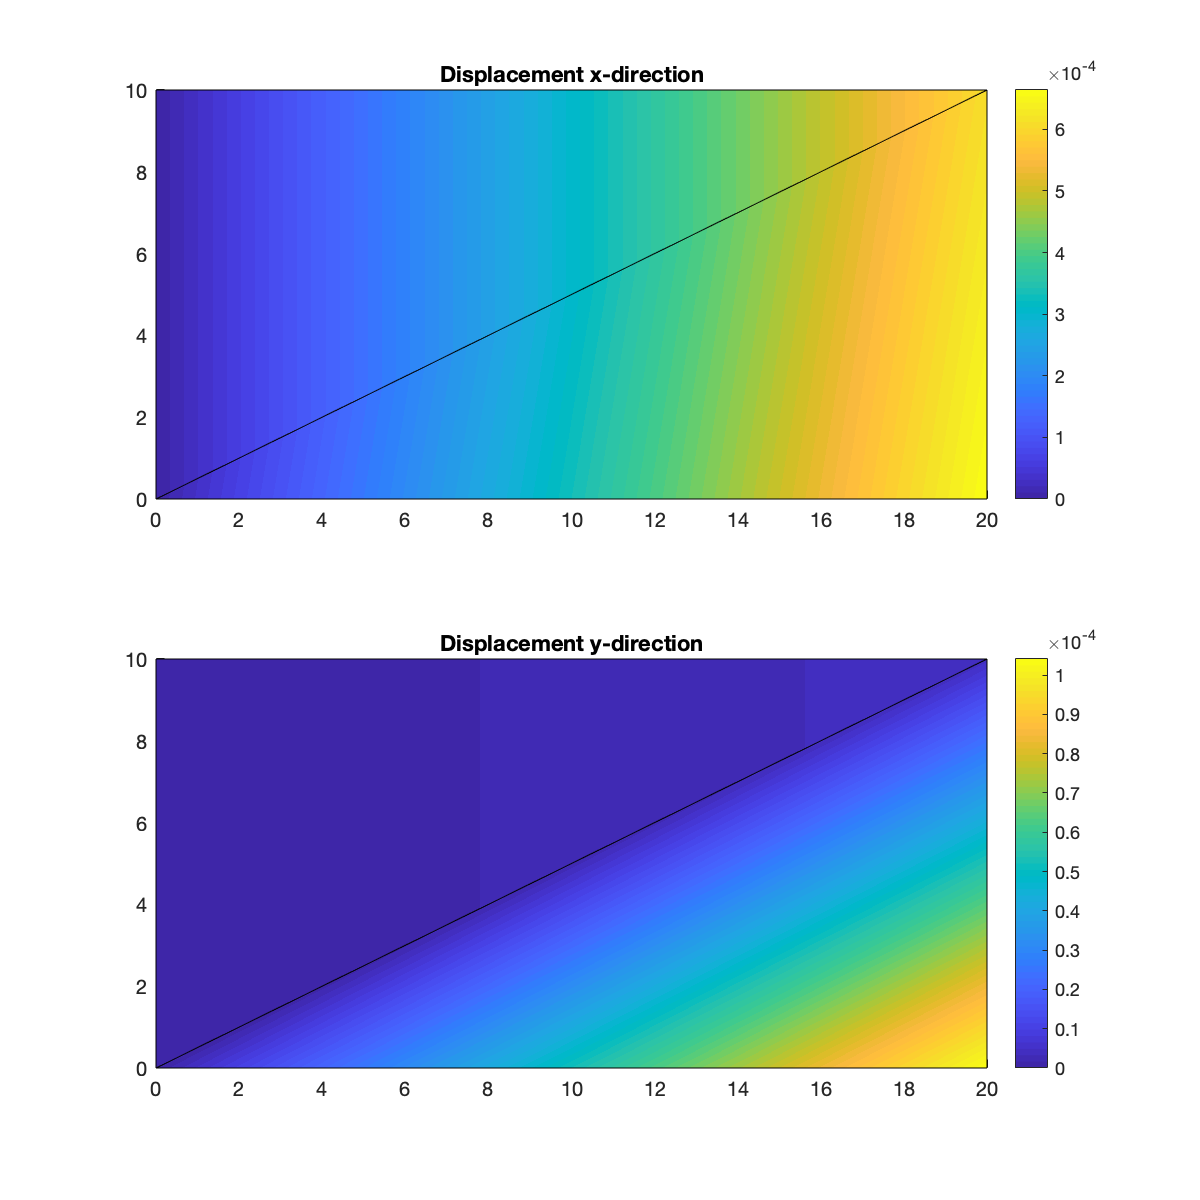



% Plot displacements
smin = min(xy);
smax = max(xy);
xyratio = (smax(1)-smin(1))/(smax(2)-smin(2));
pixel = 300;
figure('position',[ 0.1*pixel 0.5*pixel xyratio*pixel, 2*pixel ])

plot_x = subplot(2,1,1);
plot_y = subplot(2,1,2);
axis([plot_x plot_y],[smin(1) smax(1) smin(2) smax(2)])

for i = 1:NumEle
    
    xp = xy(C(i,1:3),1);
    yp = xy(C(i,1:3),2);
    cx = displacement(2*C(i,1:3)-1);
    cy = displacement(2*C(i,1:3));
    
    patch(plot_x,xp,yp,cx)
    patch(plot_y,xp,yp,cy)
    hold on;   
    
end

title(plot_x,'Displacement x-direction')
colorbar(plot_x)
title(plot_y,'Displacement y-direction')
colorbar(plot_y)
hold off;

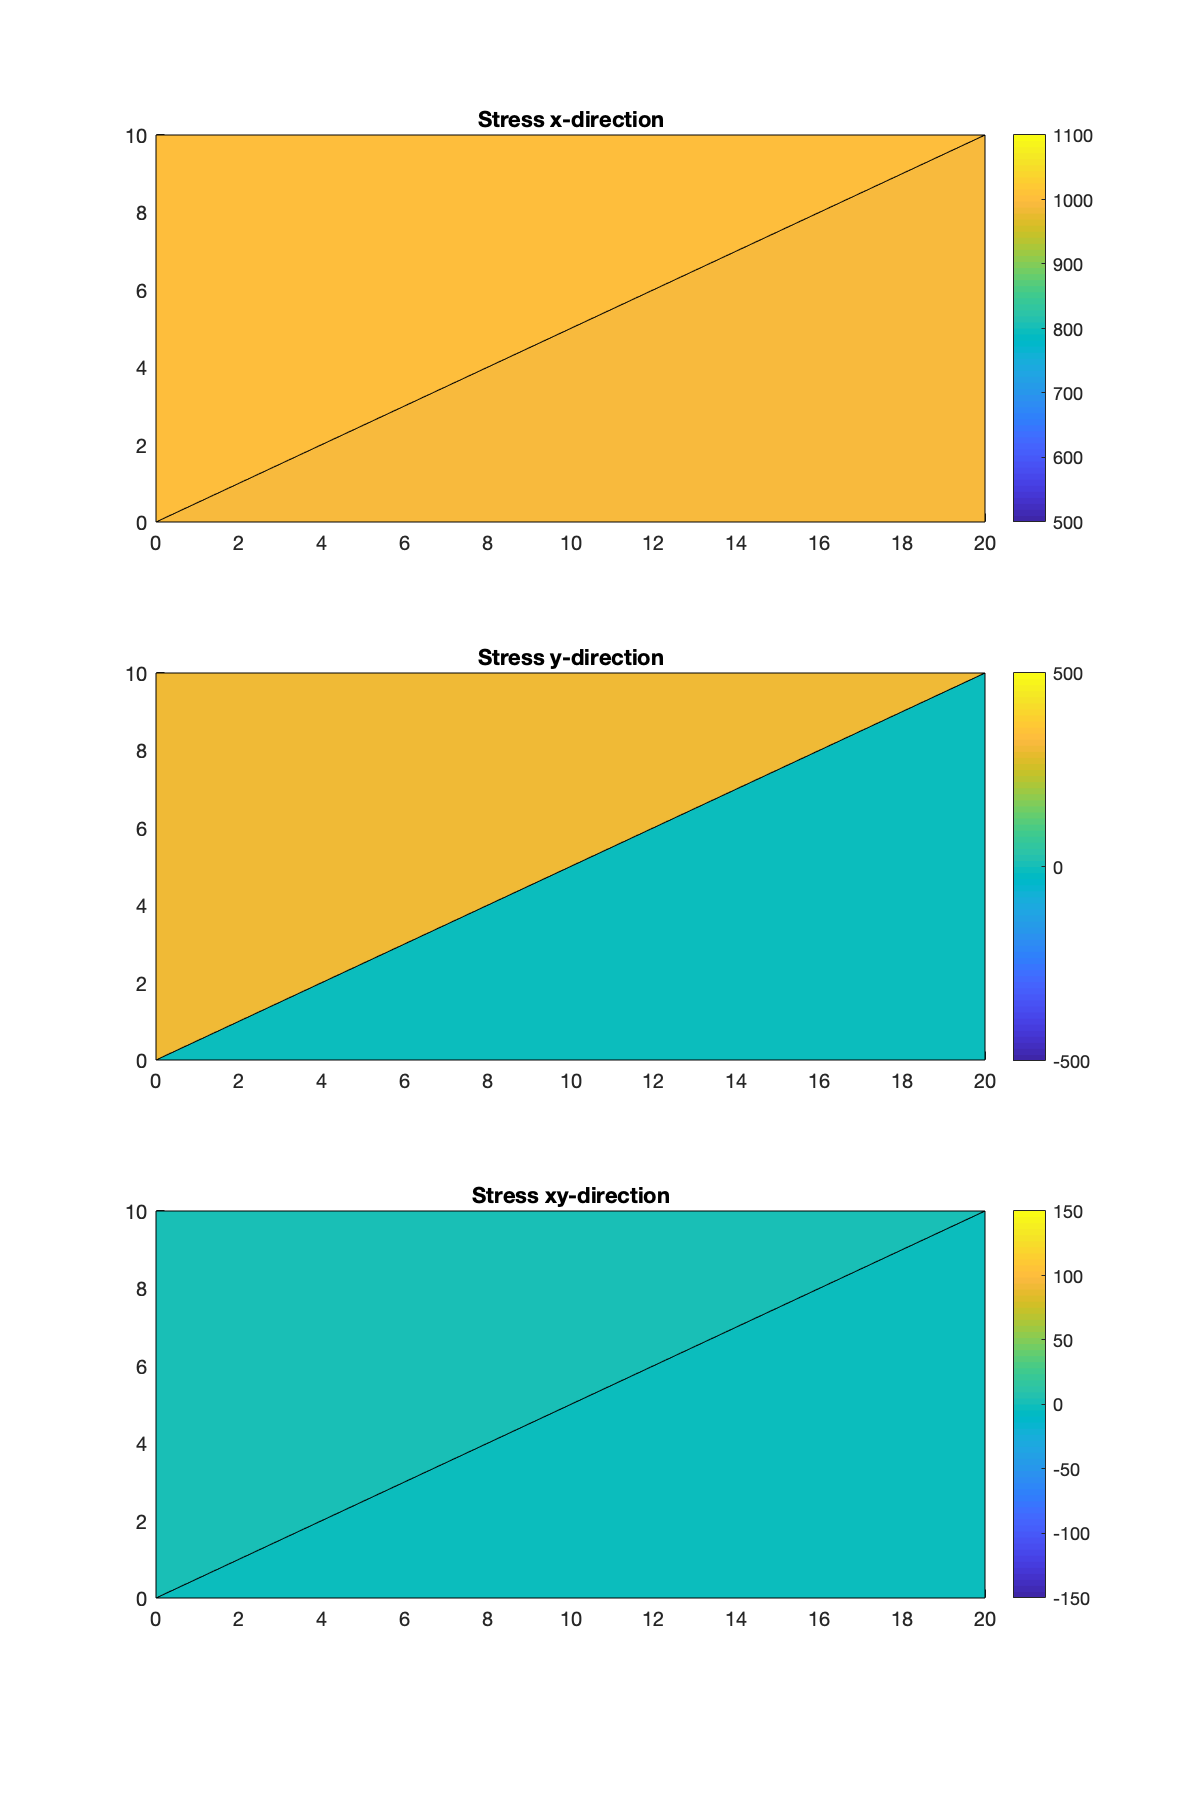



% Plot stresses
figure('position',[ 2.5*pixel 0.5*pixel xyratio*pixel, 3*pixel ])
plot_sx  = subplot(3,1,1);
plot_sy  = subplot(3,1,2);
plot_sxy = subplot(3,1,3);

sx (1:3,1) = 0;
sy (1:3,1) = 0;
sxy(1:3,1) = 0;

for i = 1:NumEle
    
    xp = xy(C(i,1:3),1);
    yp = xy(C(i,1:3),2);
    sx(1:3,1)  = Se(i,1);
    sy(1:3,1)  = Se(i,2);
    sxy(1:3,1) = Se(i,3);

    patch(plot_sx ,xp,yp, sx)
    patch(plot_sy ,xp,yp, sy)
    patch(plot_sxy,xp,yp,sxy)
    hold on;   
    
end

title(plot_sx,'Stress x-direction')
colorbar(plot_sx)
caxis(plot_sx,[500 1100])
title(plot_sy,'Stress y-direction')
colorbar(plot_sy)
caxis(plot_sy,[-500 500])
title(plot_sxy,'Stress xy-direction')
colorbar(plot_sxy)
caxis(plot_sxy,[-150 150])

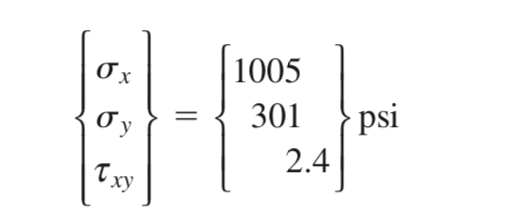for element 1

Se(1,1)

ans =      1.0048e+003


Se(1,2)

ans =    301.4412e+000


Se(1,3)

ans =      2.4019e+000


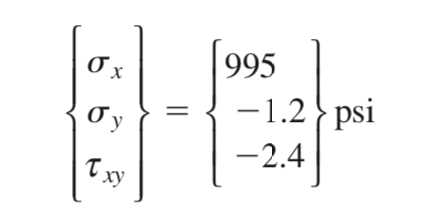for element 2

Se(2,1)

ans =    995.1962e+000


Se(2,2)

ans =     -1.2010e+000


Se(2,3)

ans =     -2.4019e+000
